% frequency shifting property 
M=10;
n=50;
n=1:M;
K=500;
tri=unitseq(min(n),M,0).*(1-(M-1-2*n)/(M-1));
[X,w]=dtft(tri,n,K);
% xf=fft(tri,1001);
figure('Name','DTFT Signal')
disp('DTFT Signal')

DTFT Signal


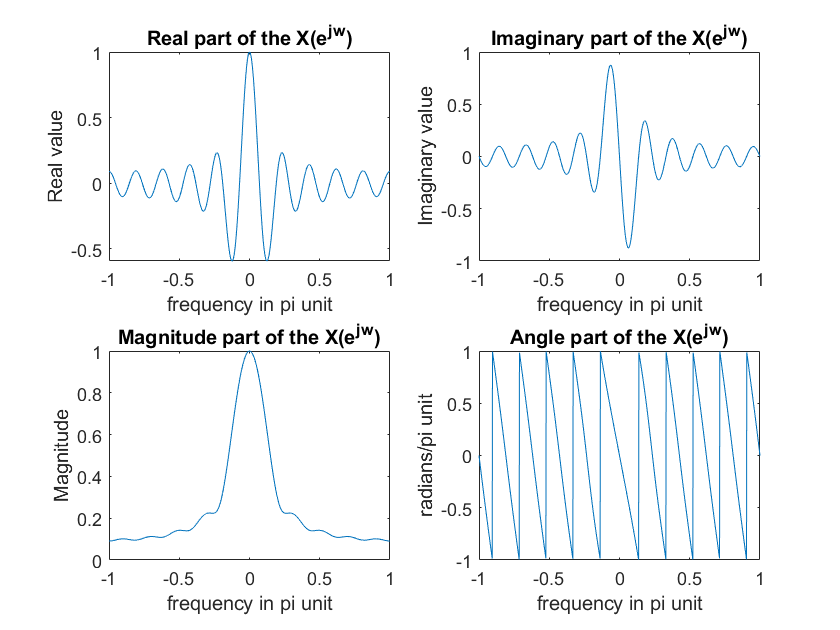

dfp4(X/max(X),w);

% figure("Name",'fft')
% disp('FFT')
% nf=1:1001;
% dfp4(xf,nf)
x=tri.*exp(1j*pi.*n);
[Xs,ws]=dtft(x,n,K);
figure("Name",'DTFT signal after right shifting by 1pi')
disp('DTFT signal after right shifting by 1pi')

DTFT signal after right shifting by 1pi


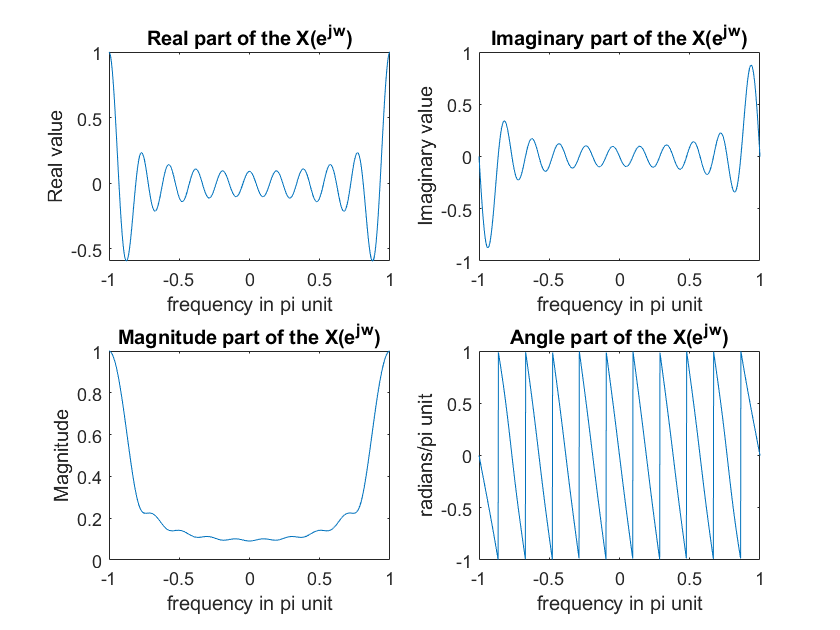

dfp4(Xs/max(Xs),ws)